# Lab 6 Proportional Speed Control 

Calculate K

T_s = 0.25; 
tau = T_s / 4;
a = 3.6029;
b = 70.3493;

s_d = -1/tau

s_d = -16

K = abs(s_d + a)/b

K = 0.1762

% coefficients
a = 3.56;
b = 66.9;
%K = 0.186;
r = 45;

% run the simulation
out = sim('Proportional_Speed_Control', 1);

F_v = mean(out.Y.Data(end-10:end)) % calculate final value

F_v = 34.5630


t = out.Y.Time(out.Y.Data >= 0.98*F_v); % calculate times above -2% final value

T_s = t(1)

T_s = 0.2598


u0 = out.u.Data(1) % initial input voltage

u0 = 7.9300


SSE = 45 - F_v % calculate steady state error

SSE = 10.4370

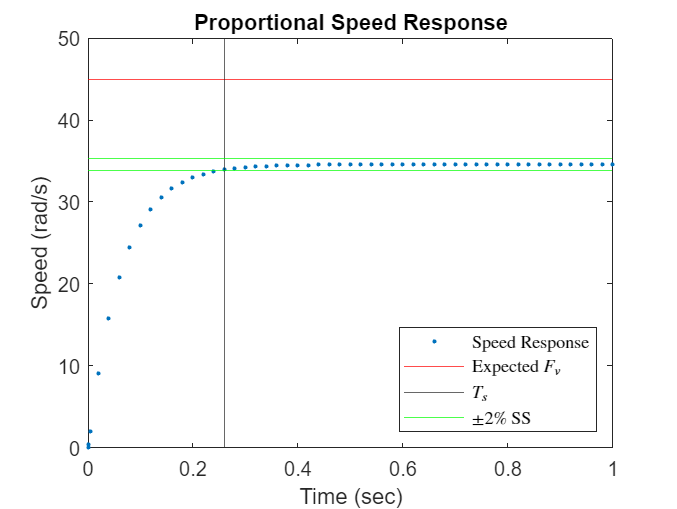

% plot speed response
plot(out.Y.Time, out.Y.Data, '.')
yline(45, 'r')
xline(t(1))
yline(F_v * 0.98, 'g')
ylim([0 50])
yline(F_v * 1.02, 'g')
title("Proportional Speed Response")
xlabel("Time (sec)")
ylabel("Speed (rad/s)")
legend({"Speed Response", "Expected $F_v$", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

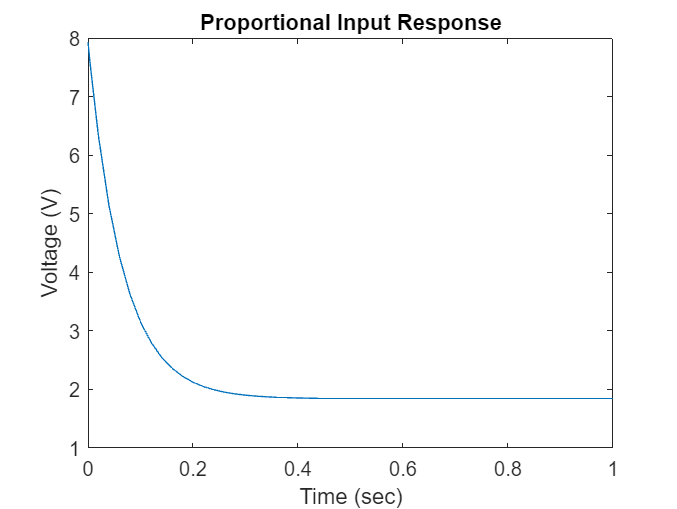


% plot input response
plot(out.u.Time, out.u.Data)
title("Proportional Input Response")
xlabel("Time (sec)")
ylabel("Voltage (V)")